# 3 Link planar arm

## Direct kinematic

we can use the symbolic toolbox, to explicitly compute the forward kinematics and then compare the solution with the one given by the toolbox so we can also plot the robot

the generic homogeneous transformation that relate $\{i-1\}$with $\{i\}$is given by:


$$A_{i}^{i-1} = R_z(\theta_i)\oplus T_z(d_i)\oplus T_x(a_i)\oplus R_x(\alpha_i)$$


but since it's planar and all joint are revolute we have $d_i = 0 ,\ \alpha_i=0\ \forall i$

syms theta_i l_i 
R_z =trotz(theta_i)

$$R\_z = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_z =sym(transl(0))

$$T\_z = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_x = transl(l_i,0,0)

$$T\_x = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{i}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_x = sym(trotx(0))

$$R\_x = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


class(R_z)

ans = 'sym'

so the homogeneous transformation between 2 frames is the following

A_i = R_z*T_z*T_x*R_x

$$A\_i = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & l_{i}\,\cos\left(\theta_{i}\right)\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & l_{i}\,\sin\left(\theta_{i}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### symbolic computation

% 1. define the symbolic variables
theta = sym('theta',[1 3]);
a = sym('a',[1 3]);

% compute the H. matrix in a recursive fashion
T0_3 = sym(eye(4));
for i = 1:3
    T0_3 = T0_3* trotz(theta(i))*transl(a(i),0,0);
end

### toolbox

DH.a = a;
three_link = Revolute('a',DH.a(1))+ Revolute('a',DH.a(2))+Revolute('a',DH.a(2));

we can know compare the two solutions

T0_3_toolbox =simplify(three_link.A([1:3],theta))

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)+a_{2}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)+a_{2}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

T0_3 = simplify(T0_3)

$$T0\_3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)+a_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)+a_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

### specifying the parameters and visualize the robot

% specify the DH parameter
DH.a = [ 1 1 1]; % all link have unit length

three_link = Revolute('a',DH.a(1))+ Revolute('a',DH.a(2))+Revolute('a',DH.a(2));
T0_3 = subs(T0_3,[a],DH.a);

% assign a value to the joint variable

qq = [pi/2,pi/3,0];

three_link.fkine(qq)

 

ans = 
   -0.8660   -0.5000         0    -1.732
    0.5000   -0.8660         0         2
         0         0         1         0
         0         0         0         1


double(subs(T0_3,theta,qq))

ans =    -0.8660   -0.5000         0   -1.7321
    0.5000   -0.8660         0    2.0000
         0         0    1.0000         0
         0         0         0    1.0000


has expected the two homogeneous transformation are the same

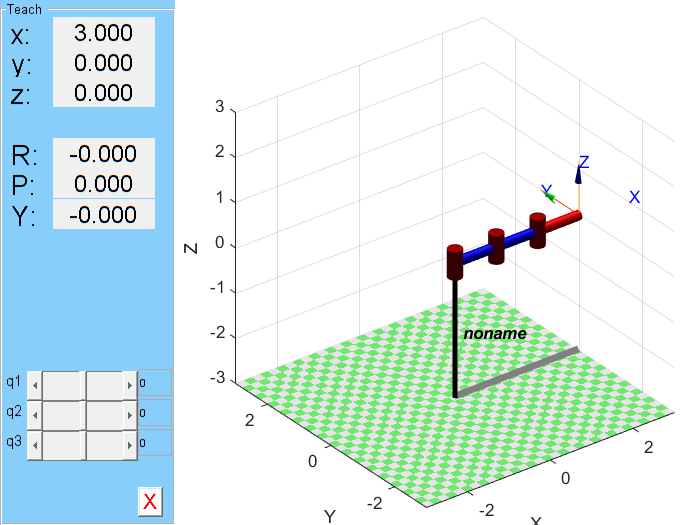

three_link.plot(qq), set(gcf,'Visible','on')
three_link.teach

function [T0_k,Rk_link] =fkine_R_k_link_planar(k)
    theta = sym('theta',[1 k]);
    a = sym('a',[1 k]);
    T0_k = sym(eye(4));
    Rk_link = Link;
    for i =1:k
        T0_k = T0_k * (trotz(theta(i))*transl(a(i),0,0));
        Rk_link = Rk_link+Revolute('a',a(i));
    end
   Rk_link = SerialLink(Rk_link.links(2:end));
    T0_k = simplify(T0_k);

end